# Hodgkin-Huxley with Applied Current Pulse

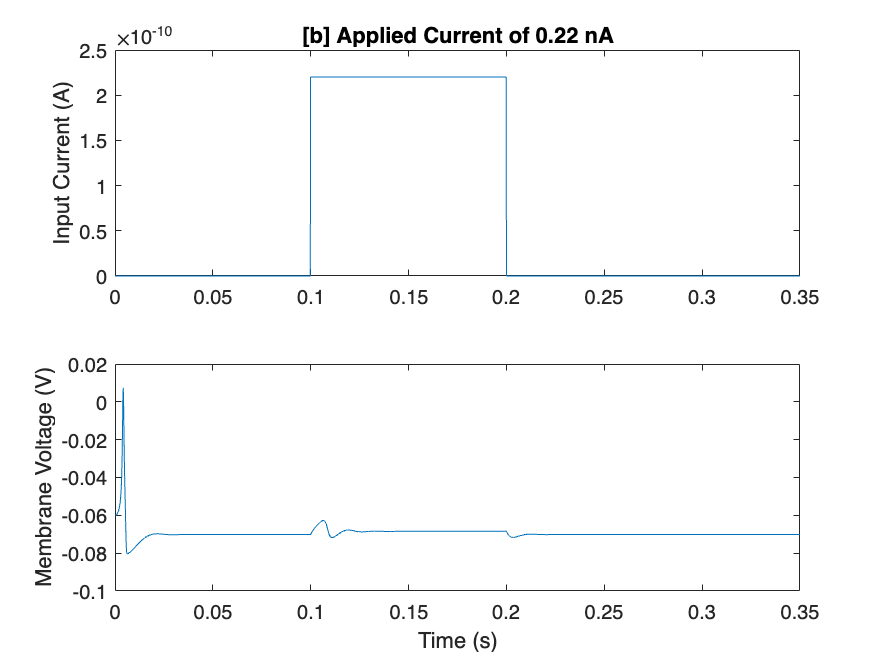

% Declare Global Parameter Values
Gl = 30e-9; % in Siemens
GNa = 12e-6; % in Siemens
Gk = 3.6e-6; % in Siemens
ENa = 45e-3; % in Volts (V)
Ek = -82e-3; % in V
El = -60e-3; % in V
Cm = 100e-12; % in Farads

% Set up time vector
t0 = 0;
dt = 0.1e-3;
t_max = .35; % in seconds
tvec = t0:dt:t_max;

% Create membrane potential vector and current vector
Vb = zeros(size(tvec));
Iappb = zeros(size(tvec));

% Create gating variable vectors
mb = zeros(size(tvec));
hb = zeros(size(tvec));
nb = zeros(size(tvec));

% Initial Conditions
Vb(1) = El;

% Create current pulse
for i = 1000:2000       % time indices corresponding to a 100ms pulse at 100 ms.
    Iappb(i) = 0.22e-9; % in Farads
end

% Run Euler's Method
for i = 2:length(tvec)
    dVbdt = (1/Cm)*(Gl*(El-Vb(i-1)) + GNa*(mb(i-1)^3)*hb(i-1)*(ENa - Vb(i-1)) + Gk*(nb(i-1)^4)*(Ek-Vb(i-1)) + Iappb(i-1));
    Vb(i) = EM(Vb(i-1), dVbdt, dt);
    dmbdt = alphaM(Vb(i-1))*(1-mb(i-1)) - betaM(Vb(i-1))*mb(i-1);
    mb(i) = EM(mb(i-1), dmbdt, dt);
    dhbdt = alphaH(Vb(i-1))*(1-hb(i-1)) - betaH(Vb(i-1))*hb(i-1);
    hb(i) = EM(hb(i-1), dhbdt, dt);
    dnbdt = alphaN(Vb(i-1))*(1-nb(i-1)) - betaN(Vb(i-1))*nb(i-1);
    nb(i) = EM(nb(i-1), dnbdt, dt);
end

% Plot Figures
figure;
subplot(2,1,1)
x = tvec;
y1 = Iappb;
plot(x, y1)
title('Applied Current of 0.22 nA')
ylabel('Input Current (A)')
subplot(2,1,2)
y2 = Vb;
plot(x, y2)
xlabel('Time (s)')
ylabel('Membrane Voltage (V)')

function y = EM(a, b, c) %Euler's Method Function
y = a + b*c;
end
function y = alphaM(x)
if exp(100*(-x-0.045))-1 == 0 % Checks for division by zero to prevent
errors
y = 0;
else
y = ((10^5)*(-x-0.045))/(exp(100*(-x-0.045))-1);
end
end
function y = betaM(x)
y = 4*(10^3)*exp((-x-0.070)/0.018);
end
function y = alphaH(x)
y = 70*exp(50*(-x-0.070));
end
function y = betaH(x)
y = 10^3/(1 + exp(100*(-x-0.040)));
end
function y = alphaN(x)
if exp(100*(-x-0.060))-1 == 0
y = 0;
else
y = ((10^4)*(-x-0.060))/(exp(100*(-x-0.060))-1);
end
end
function y = betaN(x)
y = 125*exp((-x-0.070)/0.08);
end